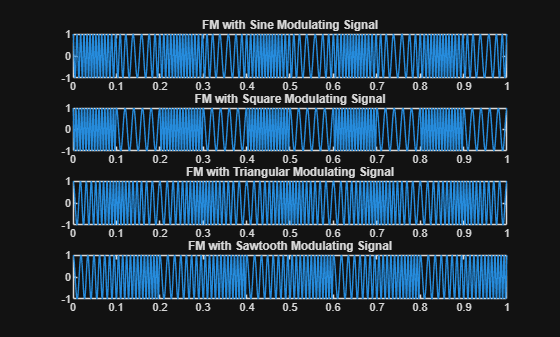

clc
clear
close all

%% Parameters
fs = 10000;          % Sampling frequency
t = 0:1/fs:1;        % Time vector

Ac = 1;              % Carrier amplitude
fc = 100;            % Carrier frequency
kf = 50;             % Frequency sensitivity

%% Carrier signal
carrier = Ac*cos(2*pi*fc*t);

%% Modulating Signals
m_sine = sin(2*pi*5*t);
m_square = square(2*pi*5*t);
m_tri = sawtooth(2*pi*5*t,0.5);
m_saw = sawtooth(2*pi*5*t);

%% FM Modulation
fm_sine = Ac*cos(2*pi*fc*t + 2*pi*kf*cumsum(m_sine)/fs);
fm_square = Ac*cos(2*pi*fc*t + 2*pi*kf*cumsum(m_square)/fs);
fm_tri = Ac*cos(2*pi*fc*t + 2*pi*kf*cumsum(m_tri)/fs);
fm_saw = Ac*cos(2*pi*fc*t + 2*pi*kf*cumsum(m_saw)/fs);

%% Time Domain Plot
figure

subplot(4,1,1)
plot(t,fm_sine)
title('FM with Sine Modulating Signal')

subplot(4,1,2)
plot(t,fm_square)
title('FM with Square Modulating Signal')

subplot(4,1,3)
plot(t,fm_tri)
title('FM with Triangular Modulating Signal')

subplot(4,1,4)
plot(t,fm_saw)
title('FM with Sawtooth Modulating Signal')

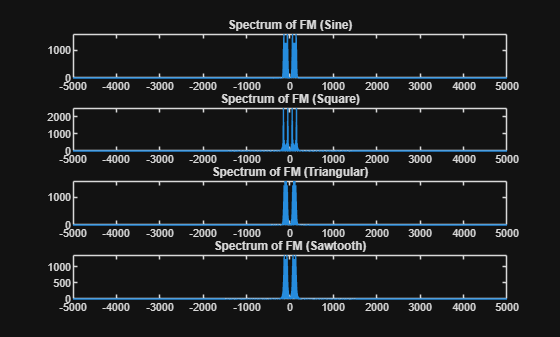


%% Frequency Spectrum using FFT

N = length(t);
f = (-N/2:N/2-1)*(fs/N);

FM1 = abs(fftshift(fft(fm_sine)));
FM2 = abs(fftshift(fft(fm_square)));
FM3 = abs(fftshift(fft(fm_tri)));
FM4 = abs(fftshift(fft(fm_saw)));

figure

subplot(4,1,1)
plot(f,FM1)
title('Spectrum of FM (Sine)')

subplot(4,1,2)
plot(f,FM2)
title('Spectrum of FM (Square)')

subplot(4,1,3)
plot(f,FM3)
title('Spectrum of FM (Triangular)')

subplot(4,1,4)
plot(f,FM4)
title('Spectrum of FM (Sawtooth)')

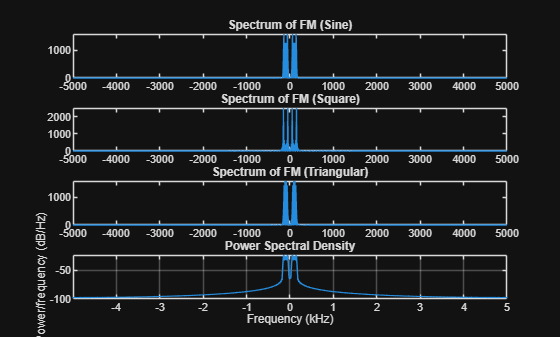

pwelch(fm_sine,[],[],[],fs,'centered')